# Círculo de Mohr (2D)

## Resumen

Script interactivo de MATLAB que enseña y aplica el método del Círculo de Mohr (2D) para la transformación de tensiones, tensiones principales y tensión cortante máxima. Incluye teoría integrada, cálculos paso a paso, gráficos dinámicos y ejemplos prácticos. Diseñado para uso educativo en Mecánica de Materiales y cursos de ingeniería afines.

## Objetivos de aprendizaje

### Objetivos de aprendizaje para docentes/instructores

Al implementar este Live Script, el docente podrá:

- Ilustrar de forma interactiva la relación entre estado tensional y su representación gráfica en el círculo de Mohr.

- Guiar a los estudiantes en un proceso paso a paso de cálculo, interpretación y verificación de resultados.

- Integrar mediciones experimentales con teoría, usando rosetas extensométricas y la ley de Hooke para esfuerzo plano.

- Evaluar la comprensión de los estudiantes mediante ejercicios rápidos y mini-quiz interactivo incluidos en el script.

### Objetivos de aprendizaje para estudiantes

Al finalizar esta actividad, el estudiante será capaz de:

- Aplicar la teoría del **Círculo de Mohr (2D)** para el análisis de esfuerzos planos.

- Calcular esfuerzos principales y cortante máximo a partir de datos directos o de roseta extensométrica.

- Interpretar y validar gráficamente resultados usando el círculo de Mohr.

- Comprobar invariantes del estado tensional (traza y diferencia de esfuerzos principales).

## Instrucciones de uso del script

### **Modo de visualización recomendado**

- Ejecute el Live Script en **MATLAB** utilizando el modo **Output inline** (*Output → Inline*).Esto permitirá que el código y los resultados (gráficas, tablas y textos) aparezcan juntos en el mismo documento, facilitando la comprensión paso a paso.

### **Ejecución por secciones**

- Es recomendable ir ejecutando el script **por secciones**, usando los botones **Run Section** o **Run and Advance** en la barra de herramientas.

Esto le permitirá:

- Analizar y comprender el efecto de cada bloque de código.

- Visualizar cómo se van actualizando las gráficas y las variables.

- Realizar modificaciones en los valores de entrada (función, límites iniciales, tolerancia, etc.) y ver de inmediato su impacto en los resultados.

## Descripción

El **Círculo de Mohr** es una representación gráfica que permite visualizar y calcular de forma sencilla:

- La **transformación de esfuerzos** cuando se rota un elemento sometido a un estado de esfuerzos.

- Los **esfuerzos principales** (máximos y mínimos) y su orientación.

- El **esfuerzo cortante máximo** y su dirección.

Fue propuesto por **Christian Otto Mohr** en 1882 y es ampliamente usado en **Resistencia de Materiales**, **Mecánica de Materiales** y **Análisis de Tensiones**.**2. ****Estado de esfuerzo plano**

En problemas bidimensionales (placas, vigas delgadas), el estado tensional se reduce a:


$$\sigma_x, \quad \sigma_y, \quad \tau_{xy}$$


con:


$$\sigma_z = \tau_{xz} = \tau_{yz} = 0$$


### **Convención de signos**:

- Esfuerzos normales de **tracción** → positivos (+).

- Esfuerzos cortantes **CCW** sobre la cara con normal en +x → positivos (+).

### **Ecuaciones de transformación**

Si el elemento se rota un ángulo θ en sentido antihorario:


$$\sigma_x(\theta) = \frac{\sigma_x + \sigma_y}{2} + \frac{\sigma_x - \sigma_y}{2} \cos 2\theta + \tau_{xy} \sin 2\theta$$



$$\sigma_y(\theta) = \frac{\sigma_x + \sigma_y}{2} - \frac{\sigma_x - \sigma_y}{2} \cos 2\theta - \tau_{xy} \sin 2\theta$$



$$\tau_{xy}(\theta) = - \frac{\sigma_x - \sigma_y}{2} \sin 2\theta + \tau_{xy} \cos 2\theta$$


### **Construcción del círculo**

El círculo se define en el plano (σ,τ)(\sigma, \tau)(σ,τ) por:


$$C = \frac{\sigma_x + \sigma_y}{2} \quad\text{(centro)}$$



$$R = \sqrt{\left( \frac{\sigma_x - \sigma_y}{2} \right)^2 + \tau_{xy}^2} \quad\text{(radio)}$$


- Punto **A**: $(\sigma_x, \tau_{xy})$

- Punto **B**: $(\sigma_y, -\tau_{xy})$

- El segmento AB es un diámetro del círculo.

### **Esfuerzos principales y cortante máximo**

#### **Esfuerzos principales**:


$$\sigma_1 = C + R$$



$$\sigma_2 = C - R$$


#### **Esfuerzo cortante máximo**:


$$\tau_{\max} = R = \frac{\sigma_1 - \sigma_2}{2}$$


#### **Orientaciones**:


$$\theta_p = \frac{1}{2} \arctan\left( \frac{2\tau_{xy}}{\sigma_x - \sigma_y} \right)$$


- Significado: es el **ángulo físico** (en el elemento real) al que hay que girar el plano de referencia para que el esfuerzo cortante sea **cero** y se obtengan los **planos principales**.

- Se mide desde la orientación inicial del plano x-y, positivo en sentido antihorario (CCW).


$$\theta_s = \theta_p + 45^\circ$$


- Significado: es el ángulo físico donde se obtiene el **esfuerzo cortante máximo** ($\tau_{max}$) en el elemento.

- Siempre es 45° después (o antes) de los planos principales en el elemento físico.

#### **Interpretación geométrica**

- La rotación física de θ en el elemento **corresponde a un ángulo 2****θ** en el círculo.

- El **eje horizontal** representa esfuerzos normales (σ).

- El **eje vertical** representa esfuerzos cortantes ($\tau$).

- Los **planos principales** corresponden a los puntos de intersección del círculo con el eje σ\sigmaσ ($\tau=0$).

#### **Aplicaciones prácticas**

- Diseño de elementos sometidos a cargas combinadas.

- Análisis de fallas según criterios como **Tresca** o **Von Mises**.

- Conversión de lecturas de extensómetros en roseta.

- Determinación rápida de orientaciones críticas.

## Entradas

Se debe tener unidades coherentes, por ejemplo, MPa

### Material

Módulo de Young [Pa]

E  = 210000000000;

Coeficiente de Poisson ($\nu$)

nu = 0.3;

Módulo de corte (derivado) [Pa]

G  = E/(2*(1+nu)); 
80769230769.23077;

Esfuerzos directos [Pa]

sigx_in  = 80000000;
sigy_in  = -20000000;
tauxy_in = 30000000;
ang_deg =  25;

Modo "rosette" (0°,45°,90°)

ε a 0°    ε a 45°    ε a 90°

eps0  = 0.00035;
eps45 = 0.00012;
eps90 = -0.00005;

## Paso 1

Definir el estado tensional de partida

Si el modo seleccionado es "Directo", utilice $\sigma_x, \quad \sigma_y, \quad \tau_{xy}$.

Si el modo seleccionado es "Rosette", convierta ε→σ (Hooke, esfuerzo plano).

Modo = 'Rosette';

if Modo == "Directo"
    sigx = 80000000;
    sigy = -20000000;
    tau =  30000000;
    modo_txt = "Directo";
elseif Modo == "Rosette"


### Entradas

    epsx  = 0.00035;

[Modo activo] ROSETTE (convertido)


    epsy  = -0.00005;


### Calculados

    gamxy = 2*eps45 - eps0 - eps90; % γxy (ingeniería)
    -0.00005999999999999999;
    sigx  = E/(1-nu^2) * (epsx + nu*epsy);
77307692.30769232;
    sigy  = E/(1-nu^2) * (epsy + nu*epsx);
12692307.69230769;
    tau   = G * gamxy;
    -4846153.846153845;
    modo_txt = "ROSETTE (convertido)";
else
    error('Modo no reconocido. Use "stress" o "rosette".');
end
fprintf('[Modo activo] %s\n', modo_txt);

### Reto (Paso 1):

a) ¿Cuándo preferirías "Rosette" en vez de "Directo"?

b) ¿Qué sucede al acercar $\nu$→0.5 en la conversión ε→σ? (mira E/(1−$\nu^{2}$))

c) Modifica $\varepsilon _{45}$ y observa el signo de $\gamma _{xy}$ y su efecto en $\tau_{xy}$.

## Paso 2 

Centro, radio y principales (derivados)

C = 0.5*(sigx + sigy);
45000000.00000001;
R = sqrt( ((sigx - sigy)/2)^2 + tau^2 );
32669132.056868497;
sig1 = C + R;
77669132.05686851;
sig2 = C - R;
12330867.94313151;
taumax = R;
32669132.056868497;

### Reto (Paso 2):

a) Con $\sigma_x$,$\sigma_y$ fijos, aumenta |$\tau_{xy}$|. ¿Cómo varían R y $\tau_{max}$?

b) Verifica el invariante: ($\sigma_1$+$\sigma_2$) − ($\sigma_x$+$\sigma_y$) ≈ 0.

c) Si $\sigma_x$=$\sigma_y$, ¿por qué R depende solo de $\tau_{xy}$?

## Paso 3

Graficar el círculo de Mohr

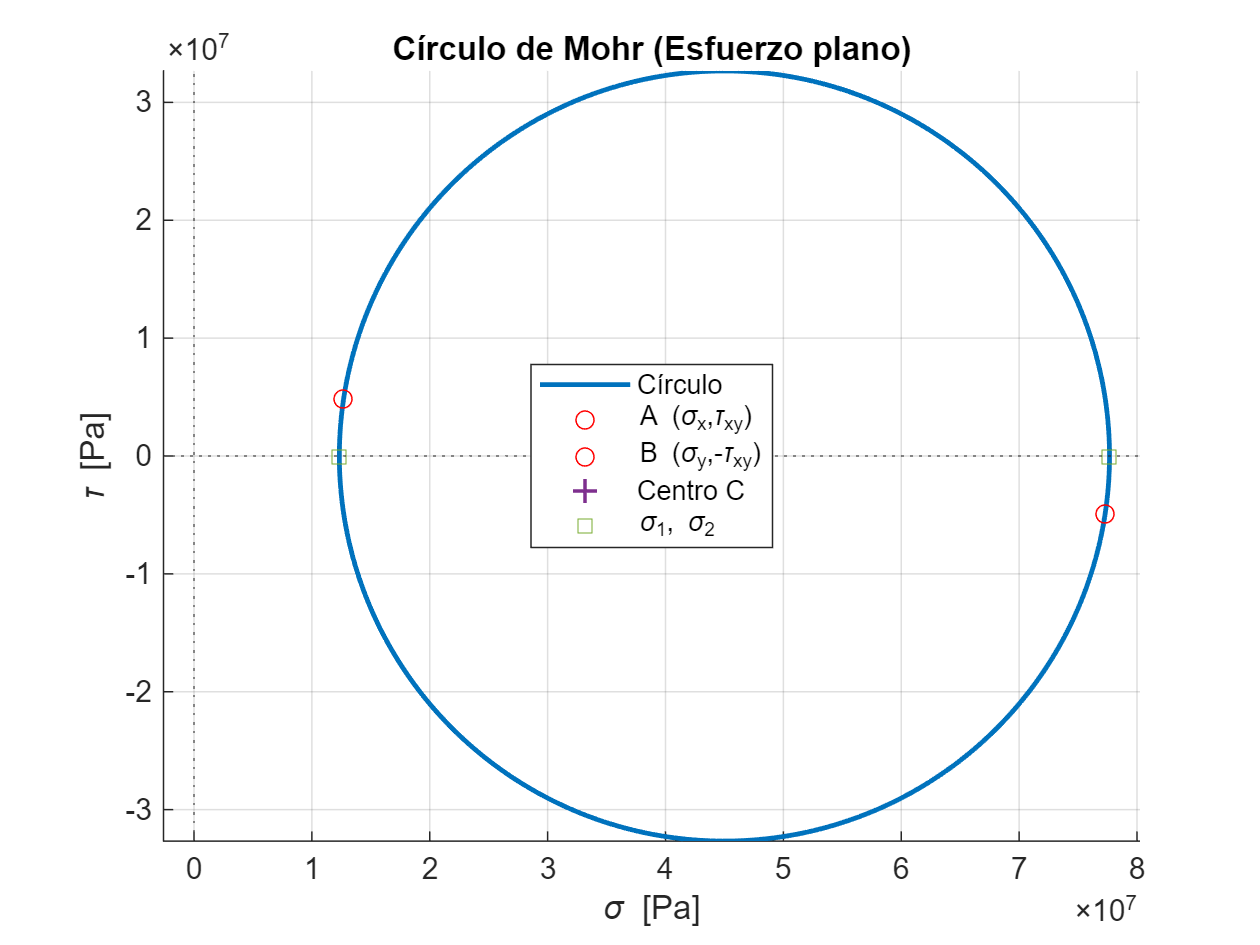

figure('Name','Círculo de Mohr — Construcción'); hold on; axis equal; grid on;
th = linspace(0,2*pi,400);
plot(C + R*cos(th), R*sin(th),'LineWidth',1.6,'DisplayName','Círculo');

xline(0,':','HandleVisibility','off'); yline(0,':','HandleVisibility','off');
xlabel('\sigma [Pa]'); ylabel('\tau [Pa]'); title('Círculo de Mohr (Esfuerzo plano)');
% Puntos A (σx,τxy) y B (σy,−τxy)
A = [sigx,  tau];
B = [sigy, -tau];
plot(A(1), A(2), 'ro', 'DisplayName','A (\sigma_x,\tau_{xy})');
plot(B(1), B(2), 'ro', 'DisplayName','B (\sigma_y,-\tau_{xy})');
% Centro y principales
plot(C,0,'+','MarkerSize',8,'LineWidth',1.2,'DisplayName','Centro C');
plot([sig1 sig2],[0 0],'s','DisplayName','\sigma_1, \sigma_2');
legend('Location','best');

### Reto (Paso 3):

a) Explica por qué la rotación en Mohr es 2θ (mira cos(2θ), sin(2θ)).

b) Cambia el signo de $\tau_{xy}$: ¿hacia dónde se mueve A?

c) Justifica la convención de signos usada para $\tau_{xy}$.

## Paso 4

Ángulos principales

th_p = 0.5*atan2(2*tau, (sigx - sigy));     % [rad]
th_p_deg = rad2deg(th_p);

(planos principales)

-4.265382804974065;
th_s_deg = th_p_deg + 45;                    % máximo cortante

(cortante máximo)

40.73461719502593;

### Reto (Paso 4):

a) Si $\tau_{xy}$=0 y $\sigma_x$≠$\sigma_y$, ¿qué valor toma θp? ¿Por qué?

b) Si $\sigma_x$=$\sigma_y$, ¿θp es único? ¿Qué implica en el círculo?

c) Comprueba que en θ=θp el punto cae en $\tau$=0 (eje $\sigma$).

## Paso 5

Transformación a un ángulo θ

**Interpretación geométrica**

- La rotación física de θ en el elemento **corresponde a un ángulo 2****θ** en el círculo.

- El **eje horizontal** representa esfuerzos normales (σ).

- El **eje vertical** representa esfuerzos cortantes ($\tau$).

- Los **planos principales** corresponden a los puntos de intersección del círculo con el eje σ\sigmaσ ($\tau=0$).

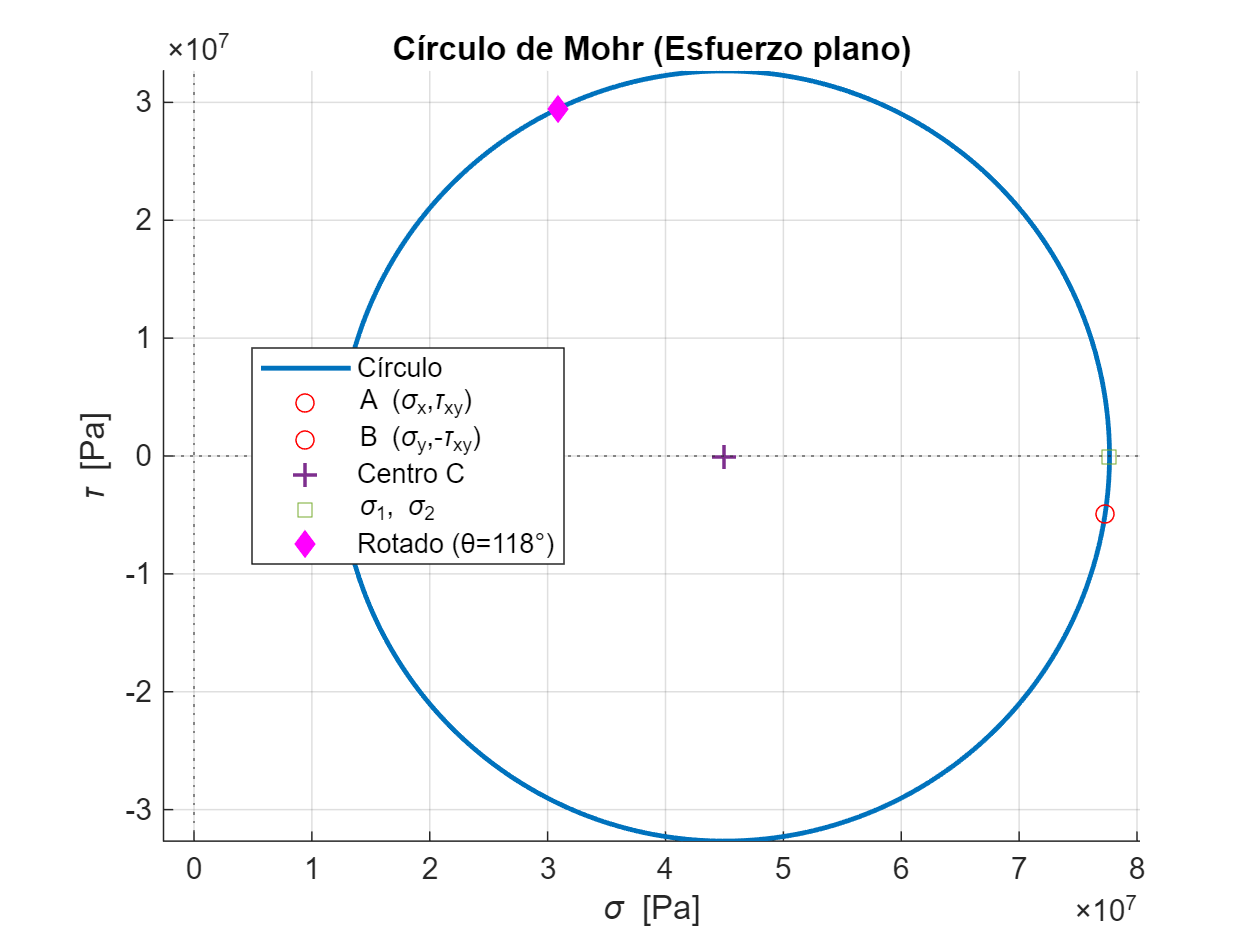

ang_deg1=118;
ang = deg2rad(ang_deg1);
sigx_rot = 0.5*(sigx+sigy) + 0.5*(sigx-sigy)*cos(2*ang) + tau*sin(2*ang);
sigy_rot = 0.5*(sigx+sigy) - 0.5*(sigx-sigy)*cos(2*ang) - tau*sin(2*ang);
tau_rot  = -0.5*(sigx-sigy)*sin(2*ang) + tau*cos(2*ang);
% fprintf('θ = %.1f° → σx(θ)=%.3e Pa, σy(θ)=%.3e Pa, τxy(θ)=%.3e Pa\n', ang_deg1, sigx_rot, sigy_rot, tau_rot);
% Punto rotado en el círculo
figure('Name','Círculo de Mohr — Construcción2'); clf; hold on; axis equal; grid on;
th = linspace(0,2*pi,400);
plot(C + R*cos(th), R*sin(th),'LineWidth',1.6,'DisplayName','Círculo');
xline(0,':','HandleVisibility','off'); yline(0,':','HandleVisibility','off');
xlabel('\sigma [Pa]'); ylabel('\tau [Pa]'); title('Círculo de Mohr (Esfuerzo plano)');
% Puntos A (σx,τxy) y B (σy,−τxy)
A = [sigx,  tau];
B = [sigy, -tau];
plot(A(1), A(2), 'ro', 'DisplayName','A (\sigma_x,\tau_{xy})');
plot(B(1), B(2), 'ro', 'DisplayName','B (\sigma_y,-\tau_{xy})');
% Centro y principales
plot(C,0,'+','MarkerSize',8,'LineWidth',1.2,'DisplayName','Centro C');
plot([sig1 sig2],[0 0],'s','DisplayName','\sigma_1, \sigma_2');
legend('Location','best');

plot(sigx_rot, tau_rot,'md','MarkerFaceColor','m', 'DisplayName',sprintf('Rotado (θ=%.0f°)',ang_deg1));

legend('Location','best');

### Reto (Paso 5):

a) Hallar θ que maximiza |$\tau_{xy}$(θ)| y comparalo con θs = θp + 45°.

b) ¿Existe θ con $\sigma_x$(θ)=$\sigma_y$(θ)? Interprétalo sobre el círculo.

c) ¿Qué cambia si θ→−θ? Observa simetrías.

## Paso 6

Tabla y verificaciones (invariantes)

Resultados = table;
Resultados.Variable = ["σx"; "σy"; "τxy"; "σ1"; "σ2"; "τmax"; "θp (°)"; "θs (°)"; "σx(θ)"; "σy(θ)"; "τxy(θ)"];
Resultados.Valor   = [ sigx;  sigy;  tau;  sig1;  sig2;  taumax;  th_p_deg;  th_s_deg;  sigx_rot;  sigy_rot;  tau_rot ];
Resultados.Unidad  = ["Pa";   "Pa";   "Pa"; "Pa";  "Pa";  "Pa";    "°";       "°";        "Pa";      "Pa";      "Pa"  ];
Resultados

Resultados = 11×3 table
    Variable       Valor       Unidad
    ________    ___________    ______

    "σx"         7.7308e+07     "Pa" 
    "σy"         1.2692e+07     "Pa" 
    "τxy"       -4.8462e+06     "Pa" 
    "σ1"         7.7669e+07     "Pa" 
    "σ2"         1.2331e+07     "Pa" 
    "τmax"       3.2669e+07     "Pa" 
    "θp (°)"        -4.2654     "°"  
    "θs (°)"         40.735     "°"  
    "σx(θ)"      3.0951e+07     "Pa" 
    "σy(θ)"      5.9049e+07     "Pa" 
    "τxy(θ)"     2.9494e+07     "Pa" 


Comprobaciones

% Invariantes
chk_traza = abs( (sig1 + sig2) - (sigx + sigy) ) < 1e-9*max(1,abs(C));
chk_delta = abs( (sig1 - sig2) - 2*R )           < 1e-9*max(1,abs(R));
fprintf('Chequeo traza (σ1+σ2 = σx+σy): %s\n', iif(chk_traza,'OK','REVISAR'));

Chequeo traza (σ1+σ2 = σx+σy): OK


fprintf('Chequeo Δσ (σ1−σ2 = 2R): %s\n',      iif(chk_delta,'OK','REVISAR'));

Chequeo Δσ (σ1−σ2 = 2R): OK


### Reto (Paso 6):

a) Cambia unidades (MPa↔Pa). ¿Se mantienen las invariantes?

b) Ajusta la tolerancia y observa cuándo fallan por redondeo.

c) Explica por qué siempre Δσ = 2R.

## Apéndice 

Roseta 0°–45°–90° (resumen)

Para una roseta alineada con x–y:

 $\varepsilon _{x}$ = $\varepsilon _{0}$,   $\varepsilon _{y}$ = $\varepsilon _{90}$,   $\gamma _{xy}$ = 2·$\varepsilon _{45}$ − $\varepsilon _{0}$ − $\varepsilon _{90}$

Conversión a esfuerzos (Hooke, ESFUERZO PLANO):


$$\sigma _{x}=\frac{E}{1-\nu ^{2}}*\left ( \varepsilon _{x}+\nu *\varepsilon _{y} \right )$$
 


$$\sigma _{y}=\frac{E}{1-\nu ^{2}}*\left ( \varepsilon _{y}+\nu *\varepsilon _{x} \right )$$



$$\tau _{xy}=G*\gamma _{xy}\; \text{con}\; G=\frac{E}{2\left ( 1+\nu  \right )}$$


**Nota:** si el problema fuera DEFORMACIÓN PLANA, usar las ecuaciones correspondientes.

## Mini-Quiz interactivo

Ejecuta esta sección para abrir una ventana con 3 preguntas.

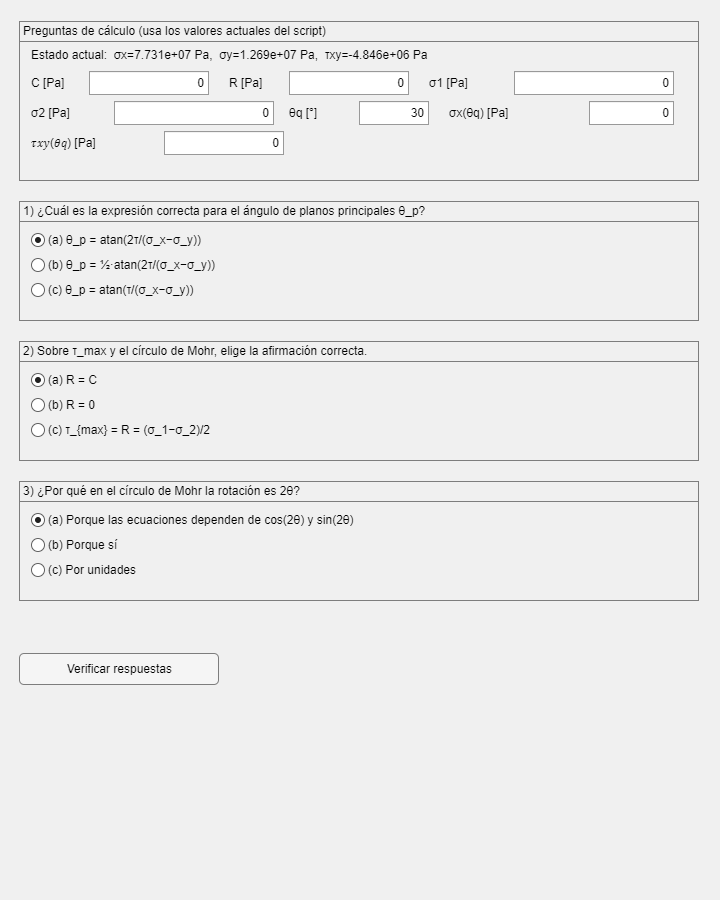

%% Mini-Quiz interactivo (Selección múltiple + Cálculo) — Copiar y pegar

% --- Garantizar variables base si no existen (toma del script o pone defaults) ---
if ~exist('sigx','var') || ~exist('sigy','var') || ~exist('tau','var')
    if exist('sigx_in','var'), sigx = sigx_in; else, sigx = 80e6; end
    if exist('sigy_in','var'), sigy = sigy_in; else, sigy = -20e6; end
    if exist('tau_in','var'),  tau  = tau_in;  else, tau  = 30e6;  end
end
if ~exist('C','var') || ~exist('R','var') || ~exist('sig1','var') || ~exist('sig2','var')
    C   = 0.5*(sigx + sigy);
    R   = sqrt(((sigx - sigy)/2)^2 + tau^2);
    sig1 = C + R; 
    sig2 = C - R;
end

% --- Ventana del quiz ---
fig = uifigure('Name','Mini-Quiz Mohr','Position',[100 100 720 900]);

% ======================= Panel de CÁLCULO =======================
calcPanel = uipanel(fig,'Title','Preguntas de cálculo (usa los valores actuales del script)', ...
    'Position',[20 720 680 160]);

uilabel(calcPanel,'Text',sprintf('Estado actual:  σx=%.3e Pa,  σy=%.3e Pa,  τxy=%.3e Pa', ...
    sigx, sigy, tau),'Position',[12 115 650 22]);

% C, R, σ1, σ2
uilabel(calcPanel,'Text','C [Pa]','Position',[12 88 60 20]);
cEdit  = uieditfield(calcPanel,'numeric','Position',[70 86 120 24]);

uilabel(calcPanel,'Text','R [Pa]','Position',[210 88 60 20]);
rEdit  = uieditfield(calcPanel,'numeric','Position',[270 86 120 24]);

uilabel(calcPanel,'Text','σ1 [Pa]','Position',[410 88 80 20]);
s1Edit = uieditfield(calcPanel,'numeric','Position',[495 86 160 24]);

uilabel(calcPanel,'Text','σ2 [Pa]','Position',[12 58 80 20]);
s2Edit = uieditfield(calcPanel,'numeric','Position',[95 56 160 24]);

% Transformación a un ángulo θq
uilabel(calcPanel,'Text','θq [°]','Position',[270 58 70 20]);
thetaEdit = uieditfield(calcPanel,'numeric','Position',[340 56 70 24],'Value',30,'Limits',[0 180]);

uilabel(calcPanel,'Text','σx(θq) [Pa]','Position',[430 58 140 20]);
sxEdit = uieditfield(calcPanel,'numeric','Position',[570 56 85 24]);

uilabel(calcPanel,'Text','𝜏𝑥𝑦(𝜃𝑞) [Pa]','Position',[12 28 130 20]);
txEdit = uieditfield(calcPanel,'numeric','Position',[145 26 120 24]);

calcLbl = uilabel(calcPanel,'Text',' ','Position',[280 26 380 22],'FontWeight','bold');

% ======================= MCQ 1 =======================
bg1 = uibuttongroup(fig,'Title','1) ¿Cuál es la expresión correcta para el ángulo de planos principales θ_p?',...
    'Position',[20 580 680 120]);
rb11 = uiradiobutton(bg1,'Text','(a) θ_p = atan(2τ/(σ_x−σ_y))','Position',[12 70 640 22]);
rb12 = uiradiobutton(bg1,'Text','(b) θ_p = ½·atan(2τ/(σ_x−σ_y))','Position',[12 45 640 22]);  % correcta
rb13 = uiradiobutton(bg1,'Text','(c) θ_p = atan(τ/(σ_x−σ_y))','Position',[12 20 640 22]);
lab1 = uilabel(bg1,'Text',' ','Position',[12 2 640 18]);

% ======================= MCQ 2 =======================
bg2 = uibuttongroup(fig,'Title','2) Sobre τ_max y el círculo de Mohr, elige la afirmación correcta.',...
    'Position',[20 440 680 120]);
rb21 = uiradiobutton(bg2,'Text','(a) R = C','Position',[12 70 640 22]);
rb22 = uiradiobutton(bg2,'Text','(b) R = 0','Position',[12 45 640 22]);
rb23 = uiradiobutton(bg2,'Text','(c) τ_{max} = R = (σ_1−σ_2)/2','Position',[12 20 640 22]);    % correcta
lab2 = uilabel(bg2,'Text',' ','Position',[12 2 640 18]);

% ======================= MCQ 3 =======================
bg3 = uibuttongroup(fig,'Title','3) ¿Por qué en el círculo de Mohr la rotación es 2θ?',...
    'Position',[20 300 680 120]);
rb31 = uiradiobutton(bg3,'Text','(a) Porque las ecuaciones dependen de cos(2θ) y sin(2θ)','Position',[12 70 640 22]); % correcta
rb32 = uiradiobutton(bg3,'Text','(b) Porque sí','Position',[12 45 640 22]);
rb33 = uiradiobutton(bg3,'Text','(c) Por unidades','Position',[12 20 640 22]);
lab3 = uilabel(bg3,'Text',' ','Position',[12 2 640 18]);

% ======================= Controles de verificación =======================
scoreLbl = uilabel(fig,'Text',' ','Position',[240 220 460 28],'FontWeight','bold');
btnCheck = uibutton(fig,'Text','Verificar respuestas','Position',[20 216 200 32]);

% Callback: corregir MCQ + Cálculo (con tolerancias)
btnCheck.ButtonPushedFcn = @(btn,evt)quizCheckPro( ...
    bg1,bg2,bg3,rb12,rb23,rb31,lab1,lab2,lab3,scoreLbl, ...
    cEdit,rEdit,s1Edit,s2Edit,thetaEdit,sxEdit,txEdit,calcLbl, ...
    sigx,sigy,tau,C,R,sig1,sig2);

## Referencias

1) R.C. Hibbeler, *Mechanics of Materials*, 10th Ed., Pearson, 2020.

2) F.P. Beer, E.R. Johnston, et al., *Mechanics of Materials*, 8th Ed., McGraw-Hill, 2020.

3) J.M. Gere, B.J. Goodno, *Mechanics of Materials*, 9th Ed., Cengage, 2018.

4) S.P. Timoshenko, J.N. Goodier, *Theory of Elasticity*, 3rd Ed., McGraw-Hill, 1970.

5) J.W. Dally, W.F. Riley, *Experimental Stress Analysis*, 4th Ed., McGraw-Hill, 2005.

6) Vishay Micro-Measurements, TN-515: *Strain Gage Rosettes: Selection, Application and Data Reduction*.

%% Función auxiliar simple
function s = iif(cond, a, b)
    if cond, s = a; else, s = b; end
end

function quizCheckPro(bg1,bg2,bg3,rb1c,rb2c,rb3c,lab1,lab2,lab3,scoreLbl, ...
    cEdit,rEdit,s1Edit,s2Edit,thetaEdit,sxEdit,txEdit,calcLbl, ...
    sigx,sigy,tau,C,R,sig1,sig2)

% --- Parte 1: múltiple opción ---
[ok1,msg1,col1] = assess(bg1.SelectedObject, rb1c);
[ok2,msg2,col2] = assess(bg2.SelectedObject, rb2c);
[ok3,msg3,col3] = assess(bg3.SelectedObject, rb3c);

set(lab1,'Text',msg1,'FontWeight','bold','FontColor',col1);
set(lab2,'Text',msg2,'FontWeight','bold','FontColor',col2);
set(lab3,'Text',msg3,'FontWeight','bold','FontColor',col3);

scoreMCQ = ok1 + ok2 + ok3;

% --- Parte 2: cálculo con tolerancia ---
relTol = 0.02;   % 2 % relativo
absMin = 1e3;    % 1000 Pa mínimo absoluto

Ctrue   = C;  Rtrue  = R;
s1true  = sig1;  s2true = sig2;

theta_q = deg2rad(thetaEdit.Value);
sx_true = 0.5*(sigx+sigy) + 0.5*(sigx-sigy)*cos(2*theta_q) + tau*sin(2*theta_q);
tx_true = -0.5*(sigx-sigy)*sin(2*theta_q) + tau*cos(2*theta_q);

okC  = assessNum(cEdit.Value,  Ctrue,  relTol, absMin);
okR  = assessNum(rEdit.Value,  Rtrue,  relTol, absMin);
okS1 = assessNum(s1Edit.Value, s1true, relTol, absMin);
okS2 = assessNum(s2Edit.Value, s2true, relTol, absMin);
okSX = assessNum(sxEdit.Value, sx_true, relTol, absMin);
okTX = assessNum(txEdit.Value, tx_true, relTol, absMin);

scoreNUM = okC + okR + okS1 + okS2 + okSX + okTX;
calcLbl.Text = sprintf('Cálculo: %d/6  (C,R,σ_1,σ_2,σ_x(θ_q),τ_{xy}(θ_q))', scoreNUM);
calcLbl.FontColor = pickcolor(scoreNUM == 6);

% Puntaje total
total = scoreMCQ + scoreNUM;   % 3 + 6 = 9
scoreLbl.Text = sprintf('Puntuación total: %d/9', total);
end

function [ok,msg,col] = assess(selObj, correctObj)
% Evalúa selección (maneja "sin selección")
if isempty(selObj)
    ok  = false;
    msg = 'Selecciona una opción';
    col = [0.47 0.47 0.47];   % gris
    return
end
ok = (selObj == correctObj);
if ok
    msg = 'Correcto';
    col = [0 0.5 0];          % verde
else
    msg = 'Revisar';
    col = [0.85 0 0];         % rojo
end
end

function ok = assessNum(userVal, trueVal, relTol, absMin)
% Acepta si |error| <= max(relTol*|true|, absMin)
if isempty(userVal) || isnan(userVal)
    ok = false; return;
end
err = abs(userVal - trueVal);
tol = max(relTol*abs(trueVal), absMin);
ok = (err <= tol);
end

function c = pickcolor(tf)
% Verde si true, rojo si false
if tf, c = [0 0.5 0]; else, c = [0.85 0 0]; end
end